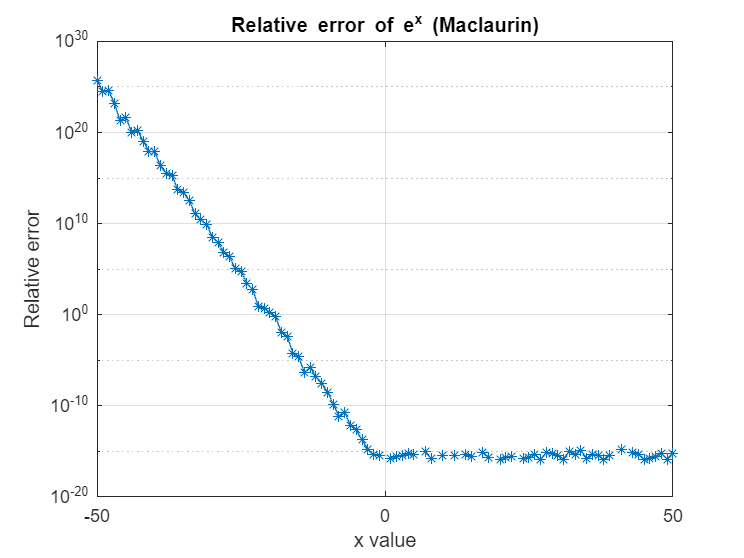

clear

xvalues = zeros(100,1);
relative_error = zeros(101,1);

x = linspace(-50,50,101);

for i = 1:101
    calc = expmac(x(i));
    actual = exp(x(i));
    relative_error(i) = abs(calc - actual) / abs(actual);
end

%loglog(xvalues, relative_error, '-*');
semilogy(x, relative_error, '-*');
grid on
title('Relative error of e^x (Maclaurin)')
xlabel('x value')
ylabel('Relative error')

function new_sum = expmac(x)
old_term = 1;
new_sum = 1;
old_sum = 0;
n = 1;

% x = 0 stops the program
    while new_sum ~= old_sum
        old_sum = new_sum;

        new_term = old_term*x/n;
        new_sum = old_sum + new_term;

        old_term = new_term;
        n = n+1;
    end
end